Pendulum on a Cart - LQR infinite horizon regulator

Constants

clear all;
close all;
clc;
M = 3; % cart mass
m = 0.5; % pendulum mass
global l;
l = 2; % pendulum length
global mu;
mu = m / (m + M); % equation parameter

State-Space matrices

% A matrix
% x = [x phi dx dphi] - state-space vector 
A = zeros(4);
A(1,3) = 1;
A(2,4) = 1;
A(3,2) = mu / (1-mu);
A(4,2) = 1 / (1-mu);
% B matrix
B = [0; 0; 1/(1-mu); 1/(1-mu)];


Choosing Q, R for LQR regulator and solving algerbraic Ricatty equation

Q = eye(4);
Q(1,1) = 0.1;
R = 1;
% solving algebraic Ricatty continous-time equation
global K;
[X1,K,L] = icare(A,B,Q,R); % K gives state-feedback matrix
K

K =    -0.3162    5.3358   -1.9345    5.1910


% solving algebraic Ricatty continous-time equation as seni-definite programming
% matrix to optimize
X = sdpvar(4,4);
% objective function
F = -trace(X); % maximize trace for stabilized solution
% constructing LMI
LMI = [X*A + A'*X + Q, X*B;
       B'*X,              R];
constr = [LMI >=0; X >=0 ] % constraints

+++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|              Constraint|   Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality 5x5|       0.1 to 2.3333|
|   #2|   Matrix inequality 4x4|              1 to 1|
+++++++++++++++++++++++++++++++++++++++++++++++++++++


opts = sdpsettings('solver', 'sdpt3', 'sdpt3.maxit', 80);
optimize(constr, F, opts);


 num. of constraints = 10
 dim. of sdp    var  =  9,   num. of sdp  blk  =  2
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.8e+01|9.5e+00|9.0e+02| 4.100000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.889|0.855|2.0e+00|1.5e+00|1.3e+02| 2.522317e+01  1.025085e+01| 0:0:00| chol  1  1 
 2|0.635|0.947|7.1e-01|8.7e-02|2.8e+01| 2.094633e+01  1.803592e+01| 0:0:00| chol  1  1 
 3|0.627|0.282|2.7e-01|6.3e-02|2.5e+01| 3.614045e+01  3.333763e+01| 0:0:00| chol  1  1 
 4|0.941|0.975|1.6e-02|1.7e-03|3.0e+00| 3.514189e+01  3.320896e+01| 0:0:00| chol  1  1 
 5|1.000|0.952|6.0e-07|4.4e-04|4.2e-01| 3.453383e+01  3.415944e+01| 0:

XX = value(X);
K1 = inv(R)*B'*XX

K1 =    -0.3162    5.3358   -1.9345    5.1910


Pendulum on a Cart Simulation

 % mass matrix

%opts = odeset('Mass', @massMtx, 'RelTol', 1e-3, 'AbsTol', 1e-3); % matrix in front of first-order derivatives
% x0 = 0;
% phi0 = -0.7;
% dx0 = 0;
% dphi0 = 0;
x0 = 0;
phi0 = -0.7;
dx0 = 0;
dphi0 = 0.4;
opts = odeset('Mass', @massMtx); % matrix in front of first-order derivatives
[t,x] = ode45(@(t,y) RHS(t, y, 'Control', true, 'Dumping', 0.2), [0 50], [x0; phi0; dx0; dphi0], opts); % x = [x phi dx dphi] state-space vector


Plotting

% Why it always tries to return the cart to the origin
% The correct sign of the dumping
% Should I take into account dumping for regulator synthesis
figure
plot(t, x(:,1))
xlabel("Time")
ylabel("X-coordinate")
title("Coordinates of the cart")

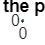

figure
plot(t,rad2deg(x(:,2)))
xlabel("Time")
ylabel("Angle")
title("Angle of the pendulum")

Animation 

L = l; % pendulum length for visualization
r = 0.25*nthroot(m, 3);
t_unit = sqrt(l/9.81); % to show animation in the real world time
% figure
% axis equal
% xlim([-5, 5])
% ylim([-1, 1.5*(L+2*r)])
% % initial position of the Pendulum on a Cart
% rec = rectangle('Position', [x0-2, 0, 4, 1], 'Curvature',0.2, 'EdgeColor', 'b');
% hold on
% line = plot([x0; x0 - L*sin(phi0)], [1; 1 + L*cos(phi0)], 'Color', 'k');
% hold on
% circle = rectangle('Position', [x0 - (L+r)*sin(phi0) - r, 1 + (L+r)*cos(phi0) - r, 2*r, 2*r], 'Curvature', [1 1], 'FaceColor', 'r', 'EdgeColor','r');
% %circle = viscircles([x0 - (L+0.25)*sin(phi0), 1 + (L+0.25)*cos(phi0)], 0.25,'Color','r');
% hold off
% for i = 1 : length(t)
%     rec.Position = [x(i,1) - 2, 0, 4, 1];
%     line.XData = [x(i,1); x(i,1) - L*sin(x(i,2))];
%     line.YData = [1; 1 + L*cos(x(i,2))];
%     circle.Position = [x(i,1) - (L+r)*sin(x(i,2)) - r, 1 + (L+r)*cos(x(i,2)) - r, 2*r, 2*r];
%     pause(50*t_unit/(length(t) -1)); % to animate in real time
%     drawnow % display updates
% end

Animation (diffferent approach)

% spline approximation of x and phi
xs_ = spline(t, x(:,1));
phis_ = spline(t, x(:,2));
xs = @(t) ppval(xs_,t);
phis = @(t) ppval(phis_,t);
% stop-motion animation using fanimator object
fanimator(@(t) rectangle('Position', [xs(t)-2, 0, 4, 1], 'Curvature',0.2, 'EdgeColor', 'b'));
axis equal;
xlim([-5, 5])
ylim([-1, 1.5*(L+2*r)])
hold on;
fanimator(@(t) plot([xs(t); xs(t) - L*sin(phis(t))], [1; 1 + L*cos(phis(t))], 'Color', 'k'));
fanimator(@(t) rectangle('Position', [xs(t) - (L+r)*sin(phis(t)) - r, 1 + (L+r)*cos(phis(t)) - r, 2*r, 2*r], 'Curvature', [1 1], 'FaceColor', 'r', 'EdgeColor','r'));
hold off;
playAnimation("FrameRate", 10, "AnimationRange", [0,20])

%playAnimation



% function dxdt = getEquation(t, x)
%     global mu;
%     global K; 
%     v = - K*x; % full-state feedback
%     fun1 = 1 - mu * cos(x(2))^2;
%     fun2 = - mu * x(4)^2 * sin(x(2));
%     dxdt = [x(3); x(4); fun1*(fun2 + mu*cos(x(2))*sin(x(2)) + v);
%             fun1*(fun2*cos(x(2)) + v*cos(x(2)) + sin(x(2)))];
% end

function mtx = massMtx(t,x)
    global mu;
    M = eye(4);
    M(3,4) = - mu * cos(x(2));
    M(4,3) = - cos(x(2));
    mtx = M;
end

function rhs = RHS(t, x, varargin)
    % default parameter
	p = inputParser; 
    p.addParameter('Control', true)
	p.addParameter('Dumping', 0); 
	p.parse(varargin{:});
    dump = p.Results.Dumping;
    control = p.Results.Control;
    global mu;
    global K;
    % example of using persistent variables
%     persistent prevTime;    
%     persistent noise;
%     noise = 0;
%     Noise = p.Results.Noise;
%     if Noise == true
%         if t == 0.0
%             prevTime = 0.0;
%             noise = randi([-2,2]);
%         end
%         if t - prevTime >= 10
%             noise = randi([-2,2]);
%         end
%     end
    if control == true
        v = -K*x; % full-state feedback
    else
        v = 0;
    end
    rhs = [x(3); x(4); -mu*x(4)^2*sin(x(2)) + v; sin(x(2)) - dump * x(4)];
end
